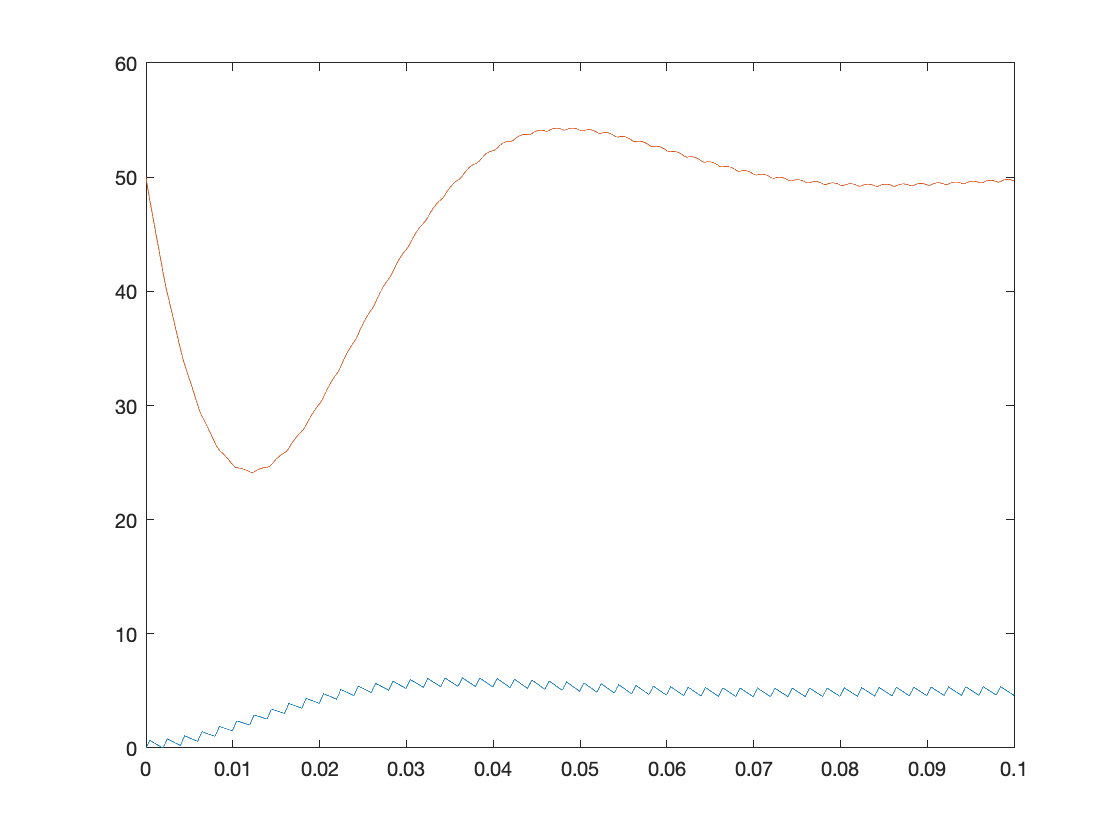

L_1=100e-03; %Coil
C=1000e-06; %Capacitor
R=10; %Resistance
T=0.002; %Duty cycle
V=200; %V_input
V_o=50;%Initial charge
decay=0.697062318; %Decay rate
%decay=0.6065029602; %Decay rate
time=1.2;%Duration of the control action simmulation
A=[0 -1/L_1; 1/C -1/R/C]; %State matrix "Buck controller"
B=[V/L_1; 0]; %Input matrix
 
%Continuous representation


Td=T/400;
N=100*(time/T);
delta=0.25;
x=zeros(2,N);
x(:,1)=[0;V_o];
for i=1:N+1
    if (mod(i,400)/400<delta)
       x(:,i+1)=x(:,i)+Td*(A*x(:,i)+B);
    else
       x(:,i+1)=x(:,i)+ Td*A*x(:,i);
    end
    if (x(1,i+1)<0)
        x(1,i+1)=0;
    end
end
figure
t=[0 (1:N+1)*Td];
plot(t,x')  
ylim([0 60])
xlim([0 0.1])

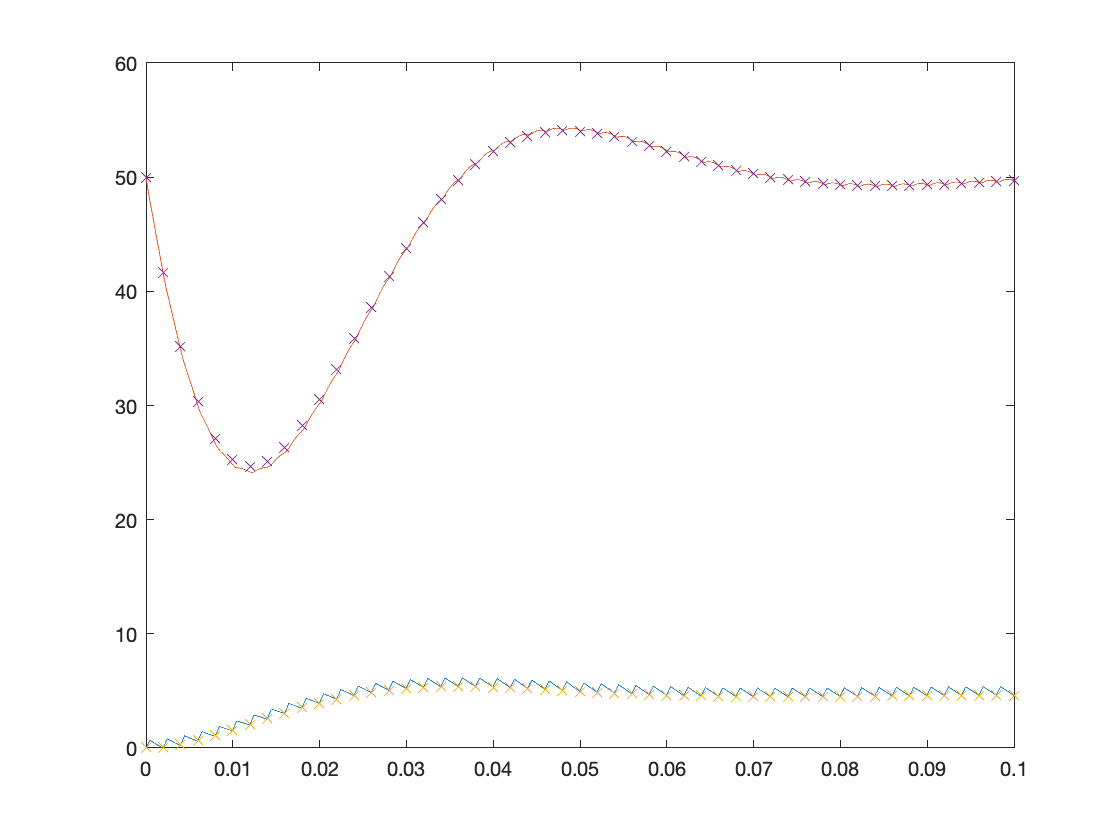




%%%%
%Discrete representation

[PA,PB,alpha2]=discrete_binary_f(A,B,T); %Fuzzy binary discretization function

%%%%%%%
delta=[0.25]; % Delta 1, the control action triggers the full duty cycle, 
%in this case, only triggers one fourth
N=50*20; %Number of cycles
x2=zeros(length(A),N);
x2(:,1)=[0,V_o]'; %Initial state
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
%Calculates each X value for each period of time.
for i=1:N+1
    x2(:,i+1)=PA*x2(:,i)+PB.eval(alpha)*delta';
end
t2=[0 (1:N+1)*T];
figure
plot(t,x') 
hold on
plot(t2,x2','x')
hold off
ylim([0 60])
xlim([0 0.1])

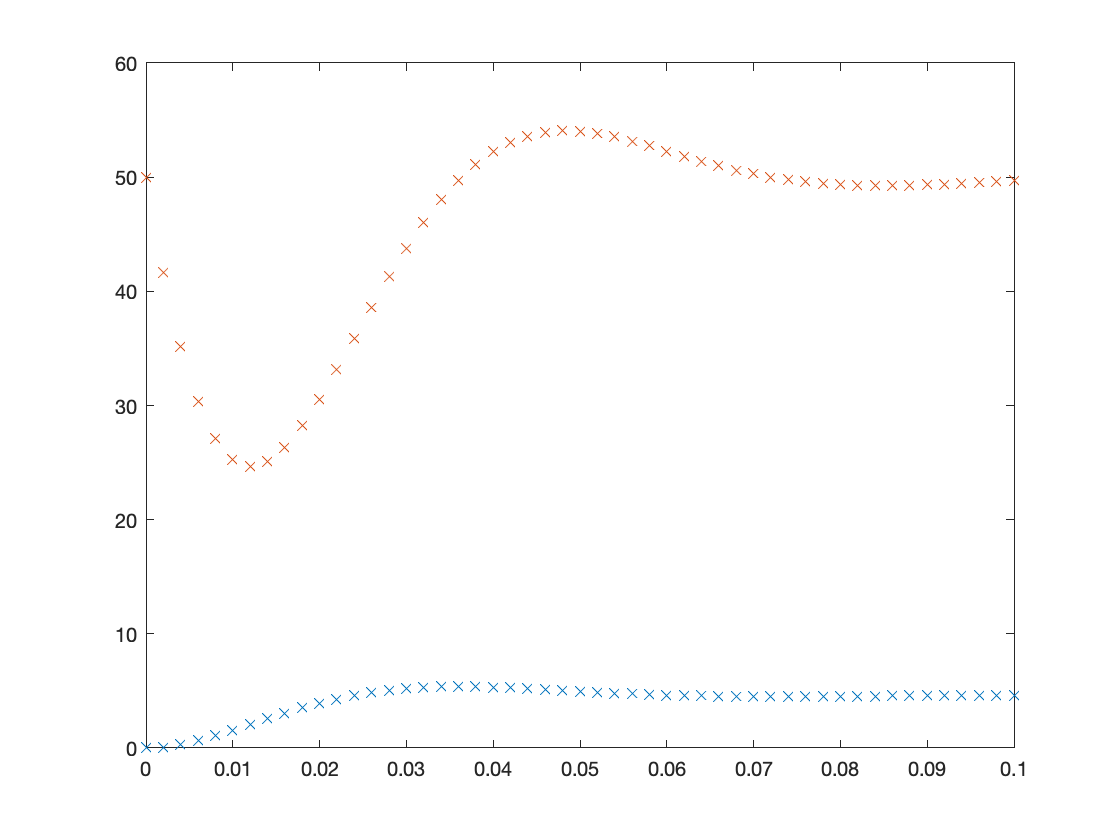

figure
plot(t2,x2','x')
ylim([0 60])
xlim([0 0.1])

%%%%%%%%%%
%Controller design:
[V,D]=eig(A);
r=rank(A);
n=length(D);
for i=1:PB.num_coef
    M{i}=sdpvar(1,n);
end
%LMI implementation
PM=MDCHP(ones(1,n),2*ones(1,n),M);%
X=sdpvar(n);
PQ=[(decay^2)*X X*PA'+PM'*PB';PA*X+PB*PM X];
%
%
PQR=PQ;
PQR.Polya([4 4 4 4]);
coef=PQR.coef;
x0=[0,V_o]';
%
LMI=[ X>=0, [1 x0';x0 X]>=1e-8];
for i=1:length(M)
    LMI=[LMI, [X M{i}';M{i} 1]>=1e-8]; 
end
for i=1:length(coef)
    LMI=[LMI coef{i}>=1e-8];
end
%LMI optimization:
optimize(LMI)

MOSEK Version 9.2.32 (Build date: 2020-12-8 22:38:36)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: MACOSX/64-X86

Problem
  Name                   :                 
  Objective sense        : min             
  Type                   : CONIC (conic optimization problem)
  Constraints            : 11              
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 31              
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number                 : 0               
Presolve terminated. Time: 0.00    
Problem
  Name   

ans = struct with fields:
    yalmipversion: '20200930'
    matlabversion: '9.9.0.1592791 (R2020b) Update 5'
       yalmiptime: 0.3509
       solvertime: 0.0775
             info: 'Successfully solved (MOSEK)'
          problem: 0


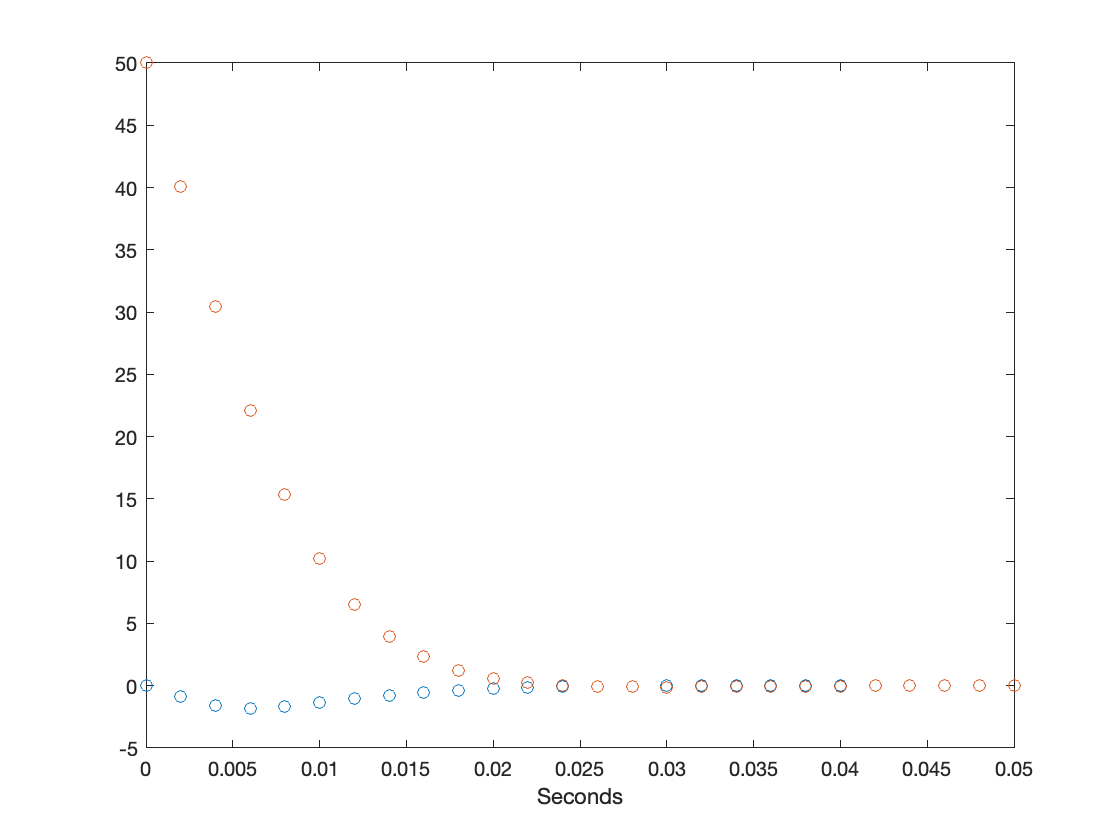

K=double(PM)*inv(double(X));
%Controller result:
K.array();
%
%
%
%Controller iterative result for each period of time:
x=zeros(n,time/T);
x(:,1)=x0;
muT=[];
alpha_sat1=[];
alpha_sat2=[];
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
for i=1:length(x)
    Ki=K*x(:,i);
    aux=0;
    delta=sum(Ki.array())/Ki.num_coef();
    delta=delta*(delta<1)*(delta>0)+(delta>1);
    delta_ant=-1;
    while (aux<20)&&(abs(delta-delta_ant)>1e-6);
        aux=aux+1;
        delta_ant=delta;
        alpha=[];
        for j=1:r
           alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
        end
        delta=Ki.eval(alpha);
        delta=(delta+delta_ant)/2;
    end
    aux;
    delta;
    alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        alpha=alpha_sat1;
    end
    muT=[muT delta];
    x(:,i+1)=PA*x(:,i)+PB.eval(alpha)*delta;
end


t3=[0 (1:i)*T];
figure
plot(t3,x','o')
%title('Controlled response over time of analisis:')
xlabel('Seconds')
ylim([-5 50])
xlim([0 0.05])

figure
x4=(muT);
t4=[0 (1:length(muT)-1)*T];
plot(t4,x4','o')
%title('Control action over the time of analisis:')
xlabel('Seconds')
Max_control_action=max(muT)

Max_control_action = 0.1350

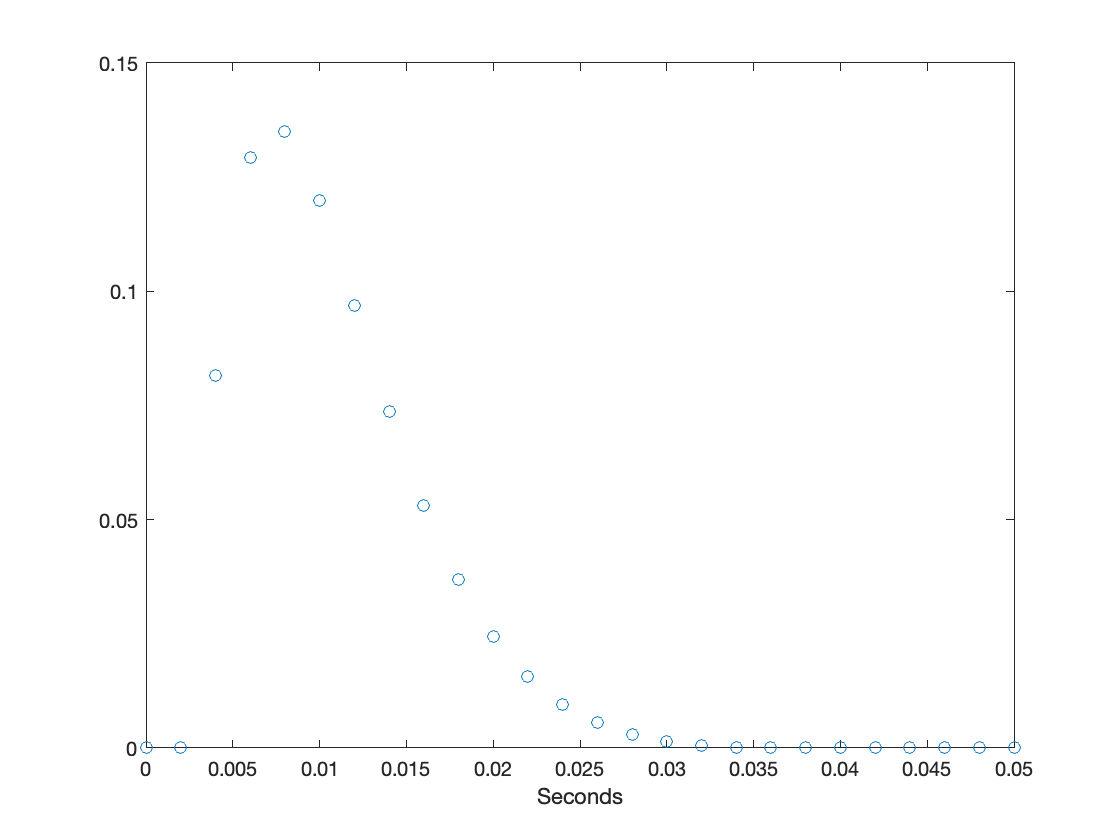

ylim([0 0.15])
xlim([0 0.05])